
clear;clc;close all;
set(0,'defaultlinelinewidth',3)
set(0,'defaultaxeslinewidth',2);
set(0,'defaultaxesfontsize',28);
set(0,'defaulttextfontsize',28);
set(0,'DefaultLineMarkerSize',28);
set(0,'Defaultaxesfontname','Times New Roman');
% addpath('./circleData');

% figure(); box on;
% plot(x/D,U0_axi,'-');
% xlabel('$x/D$','interpreter','latex');
% ylabel('$U_0$','interpreter','latex');
% set(gcf,'unit','centimeters','position',[20 20 20 20])

% saveas(gcf,'Re_80_U0_axi','epsc')

简单抽样计算


$$I=\int_{-2}^2 f\left(x\right)\;\textrm{dx}\;$$


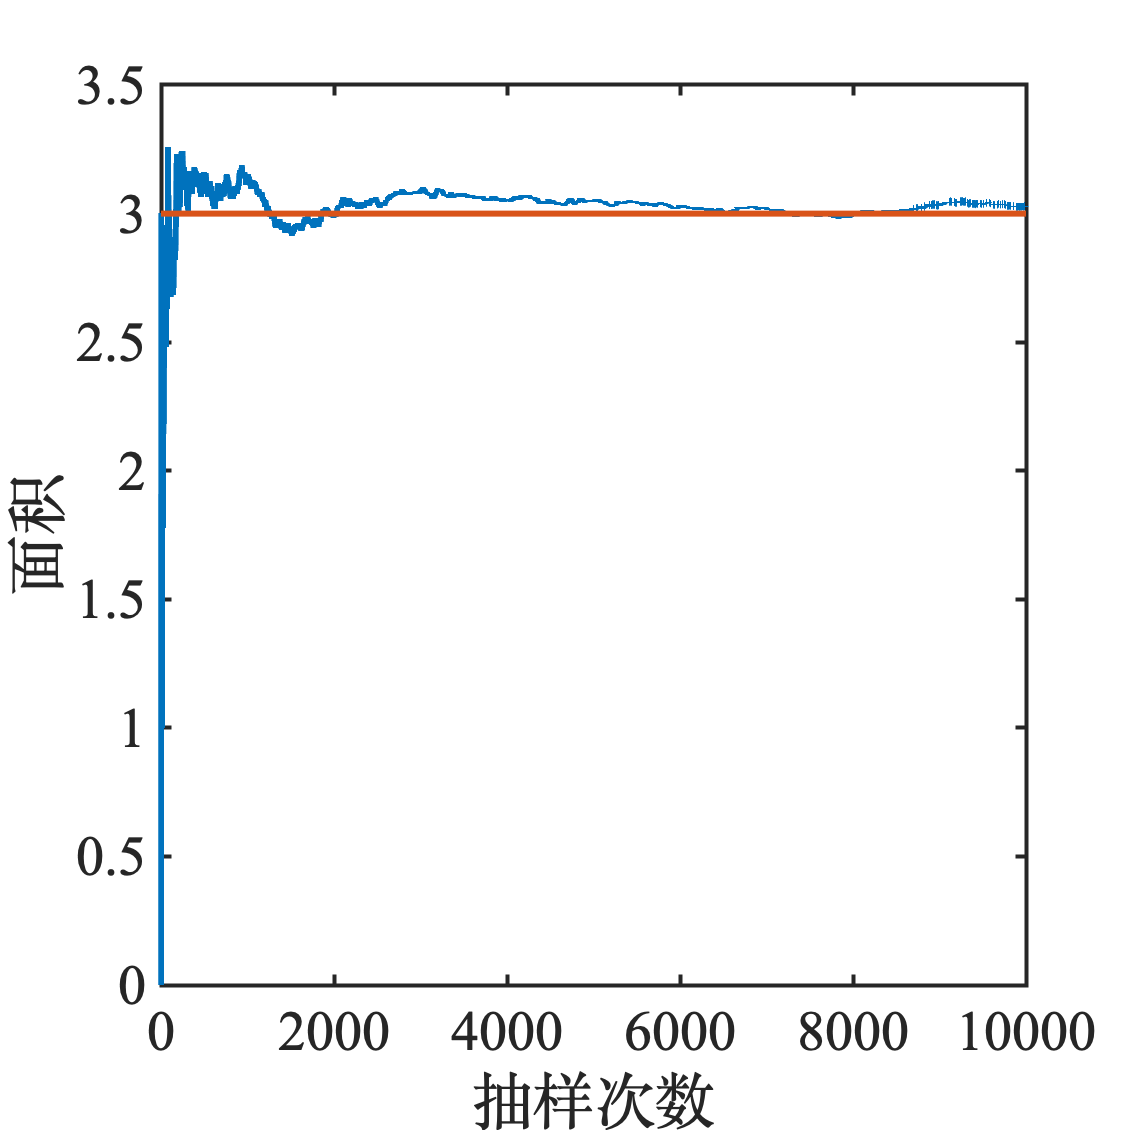

num = 1e4;
point = 0;
all = 0;
x = 0;
y = 0;
x1 = 0;
y1 = 0;
for i = 1:num
    a = rand * 4 - 2;
    b = rand * 3;
    if a < 1 && a > -1
        if b < 3 - abs(a) * 3.0
            x1(i) = a;
            y1(i) = b;
            point = point + 1;
        else
            x(i) = a;
            y(i) = b;
        end
    else
        x(i) = a;
        y(i) = b;
    end
    all = all + 1;
    ratio(i) = 12 * point / all;
end

figure(); box on;
plot(ratio);
hold on;
plot([0,num],[3,3]);
xlabel('抽样次数');
ylabel('面积');
% xlim([0 5000])
set(gcf,'unit','centimeters','position',[20 20 20 20])
% legend('正面','反面')
hold off;
saveas(gcf,'1','epsc')

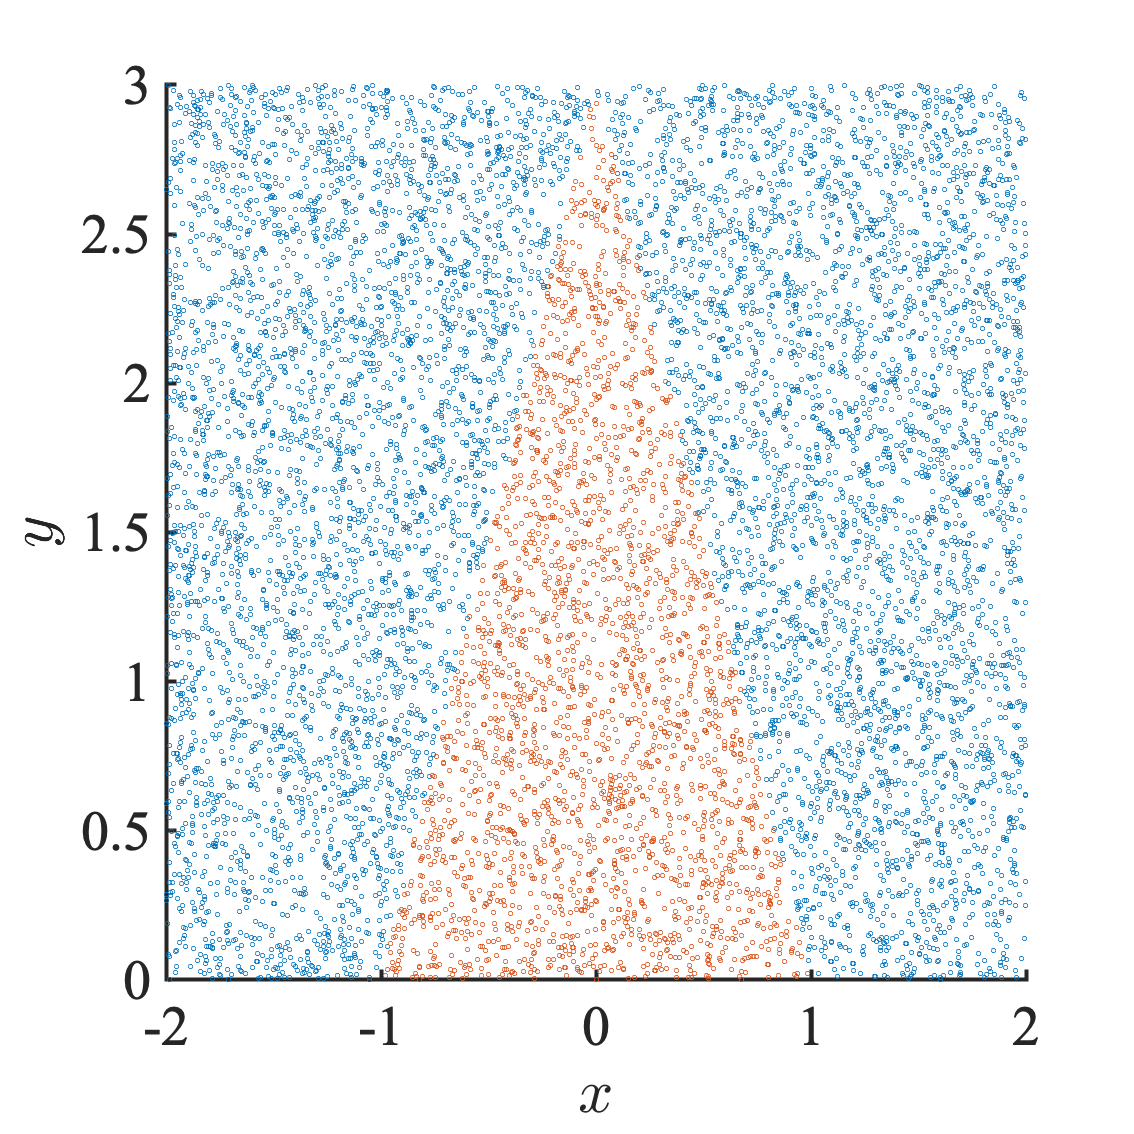


scatter(x,y,6)
hold on;
scatter(x1,y1,6)
hold off;
xlabel('$x$','interpreter','latex');
ylabel('$y$','interpreter','latex');
saveas(gcf,'2','epsc')

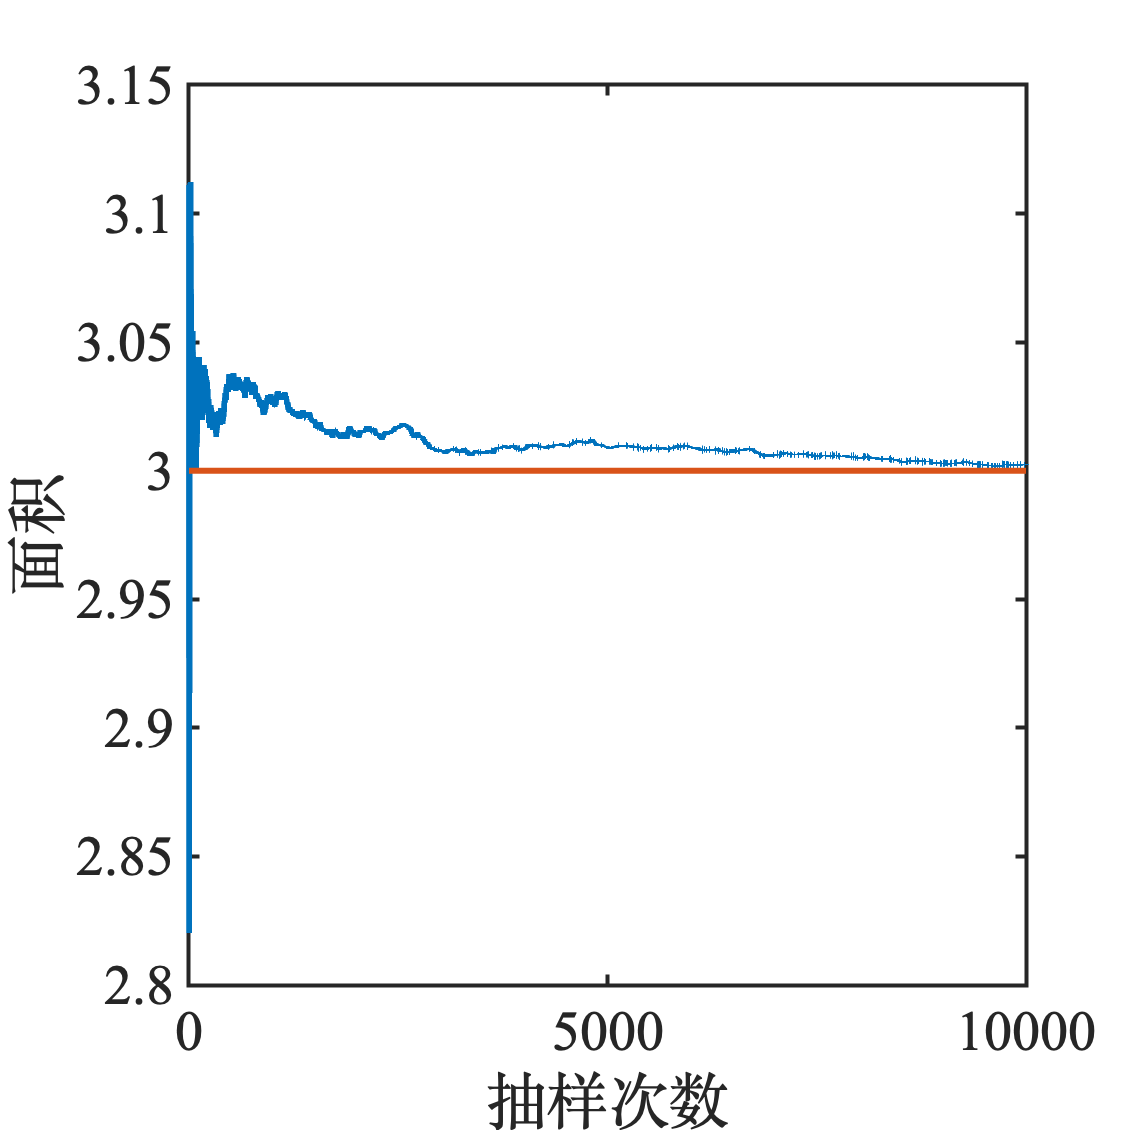

% num = 1e4;
point = 0;
all = 0;
x = 0;
y = 0;
x1 = 0;
y1 = 0;
sum = 0;
ratio1 = 0;
for i = 1:num
    a = 2 / pi * asin(rand) * sign(rand-0.5);
    b = rand * 3;
    x(i) = a;
    sum = sum + 2*(3 - 3*abs(a))/(pi/2*cos(pi/2*a));
    
    all = all + 1;
    ratio1(i) =  sum / all;
end

figure(); box on;
plot(ratio1);
hold on;
plot([0,num],[3,3]);
xlabel('抽样次数');
ylabel('面积');
set(gcf,'unit','centimeters','position',[20 20 20 20])
% legend('正面','反面')
hold off;
saveas(gcf,'3','epsc')


% scatter(x,y,6)
% scatter(x1,y1,6)
% hold off;
% xlim([-2 2])
% xlabel('$x$','interpreter','latex');
% ylabel('$y$','interpreter','latex');
% saveas(gcf,'4','epsc')


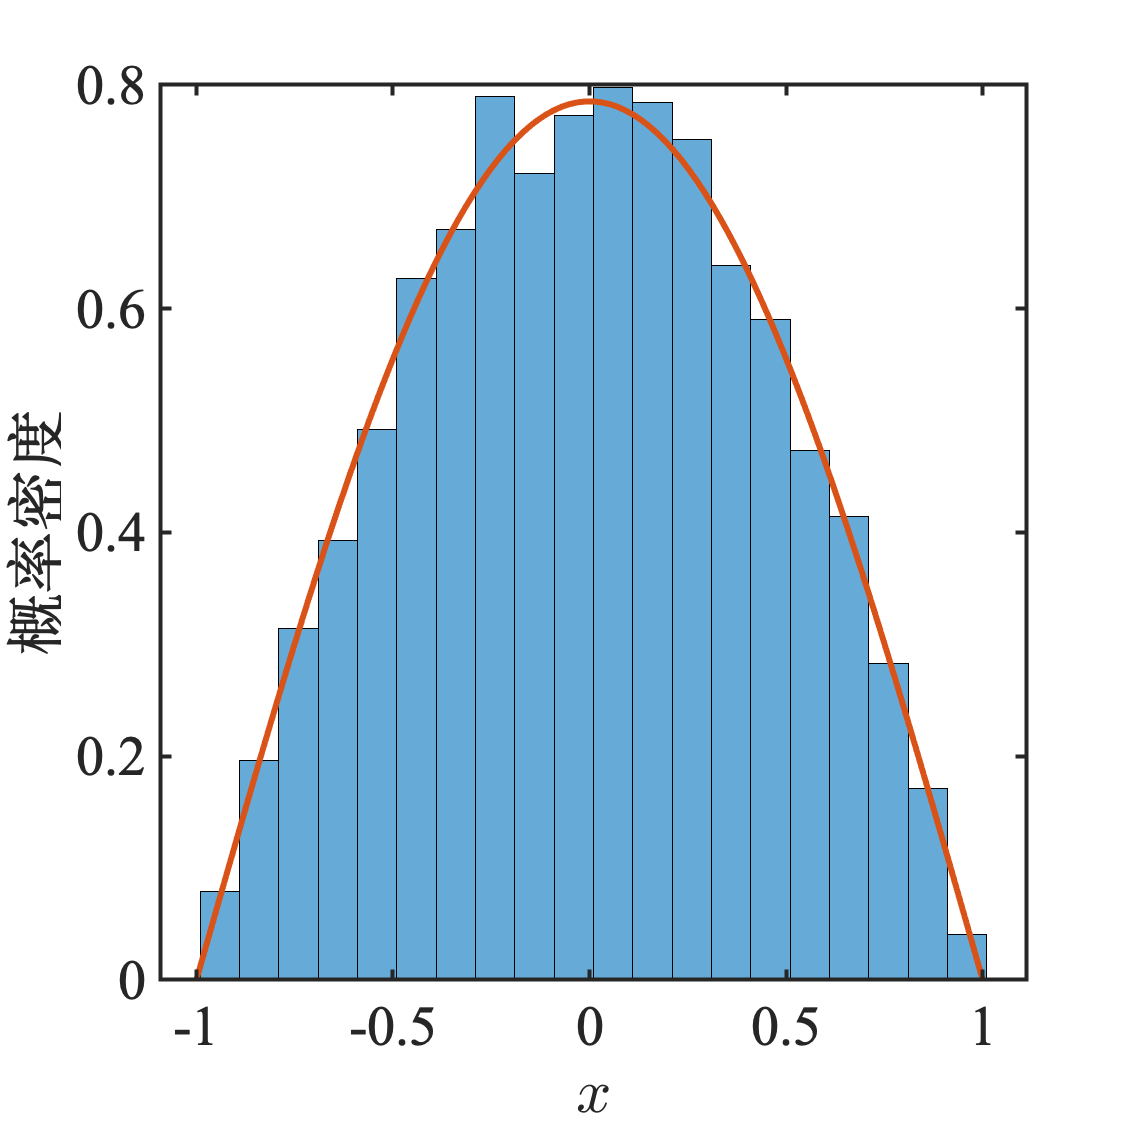


histogram(x,20,'Normalization','pdf');
hold on;
t = linspace(-1,1,100);
plot(t,pi/4*cos(t*pi/2))
hold off;
xlabel('$x$','interpreter','latex');
ylabel('概率密度');
saveas(gcf,'4','epsc')

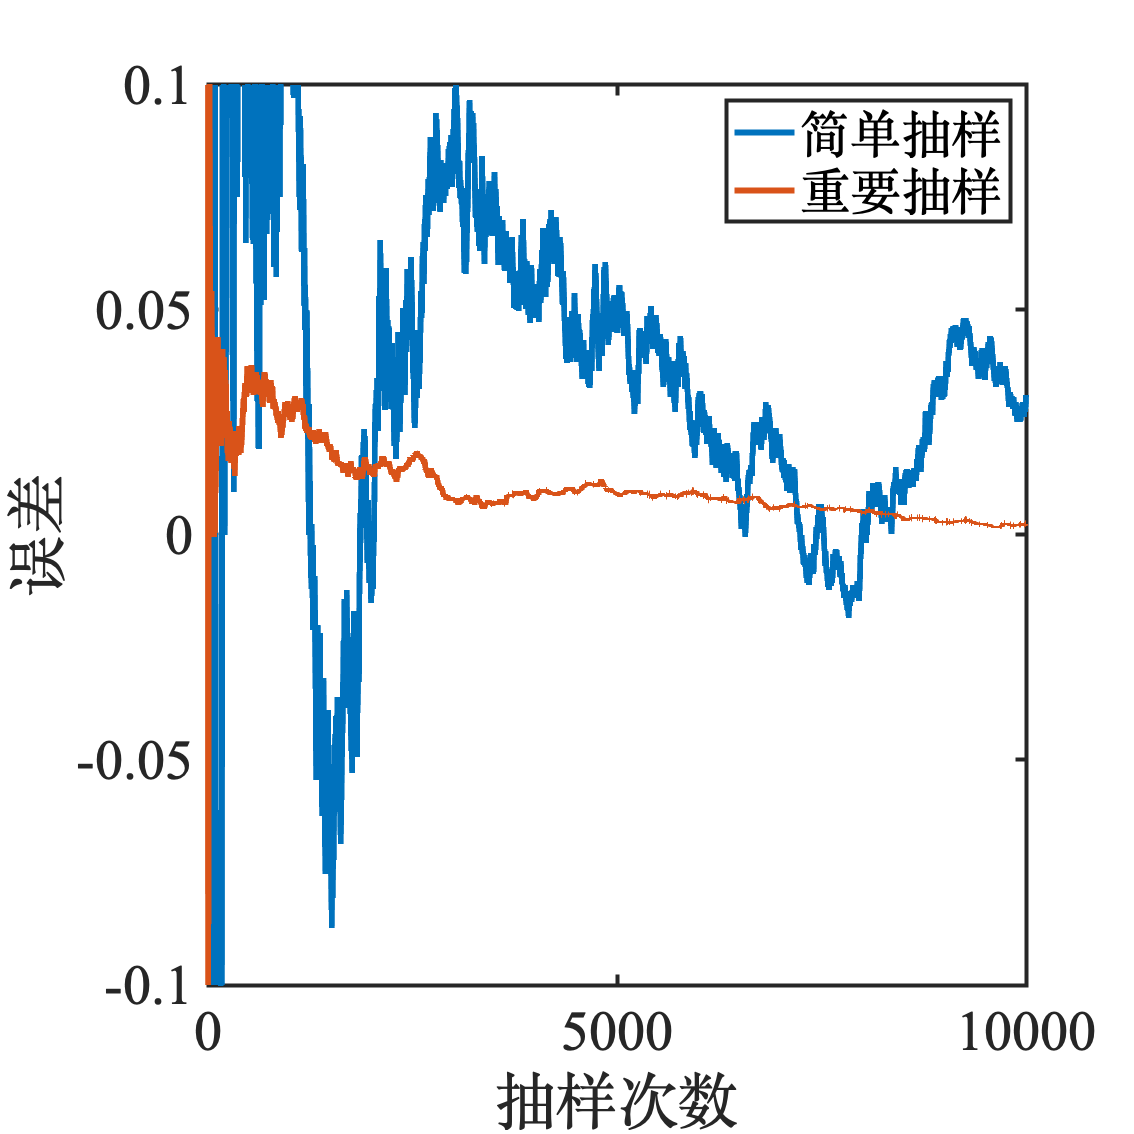

plot(ratio-3)
hold on;
plot(ratio1-3)
hold off;
ylim([-0.1 0.1])
legend('简单抽样','重要抽样')
xlabel('抽样次数');
ylabel('误差');
saveas(gcf,'5','epsc')